%Report 1. Basic NPD model
%Hello
%Themistoklis Konstantinopoulos s210232

%Initial Variables - 
H=30; %half-saturation constant of light-limitead growth (μmol *  m^-2  * day^-1)
Iin=300; %incident light intensity (μmol * m^-2 * day^-1)
Kbg=0.0375; %backround turbidity (m^-1)
k=0.05; % specific light attenuation of phytoplankton (m^2*cell^-1)
l=0.03; %specific loss rate (day^-1)
Pmax=0.5; %maximal specific production rate (day^-1)
u=12; %vertical velocity (m*day^-1)
L=200; %water column depth (m)
delta=1; %m
z=0.5*delta:delta:L; %cell centre
steps=length(z); %number of steps
phi0=(0.001)*ones(1,steps)'; %initial parameters (cells * m^-3)
time=(1:1:6000)'; %days
Den=zeros(1,steps)'; %initial dentritus (mmolN*m^-3)
N0=5*ones(1,steps); %initial nutrients (mmolN*m^-3)
N0(end)=30; %initial nutrients bottom (mmolN*m^-3)
eps=0.1; %nutrient recycling coef
Hn=0.3; % half saturation for nitrogen
gamma=1.5; % grazing (m^3*mmolN^-1*d^-1)
y=[phi0' N0 Den'];
Du=43;%turbulent diffusion top(m^2 * day^-1)
Dd=5;%turbulent diffusion bottom(m^2 * day^-1)
w=1; %depth of mixing zone (m)
Zmix=50; %depth of UML (m)
%Running ODE
[~,dy]= ode45(@(time,y) report1(time,y,Dd,Du,w,delta,u,Pmax,H,Iin,k,Kbg,l,eps,Hn,gamma,Zmix,steps),time,y);


%Graphs

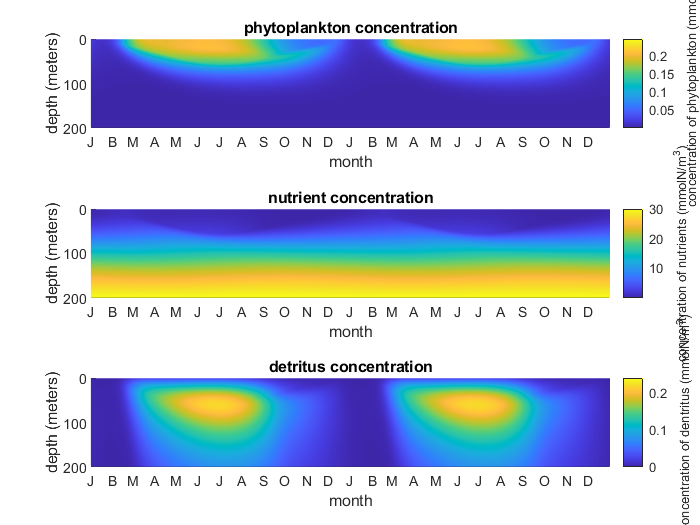

%Graph of phytoplankton
tiledlayout(3,1)
nexttile
Ptest=dy(:,1:steps);
surface(time,z,Ptest')
set(gca,'Ydir','reverse')
xlabel('month')
ylabel('depth (meters)')
c = colorbar;
c.Label.String = 'concentration of phytoplankton (mmolN/m^{3})';
shading interp;
title('phytoplankton concentration')
xlim([365*10 365*12])
r=365;
r1=365*10;
r2=365*11;
xticks([r1, r1+31,r1+59,r1+90,r1+120,r1+151,r1+181,r1+212,r1+243,r1+273,r1+304,r1+334,r2, r2+31,r2+59,r2+90,r2+120,r2+151,r2+181,r2+212,r2+243,r2+273,r2+304,r2+334])
xticklabels({'J','B','M','A',"M",'J','J','A','S','O','N','D','J','B','M','A',"M",'J','J','A','S','O','N','D','J'})
nexttile
%Graph of nutrients
surface(time,z,dy(:,(steps+1):2*steps)')
set(gca,'Ydir','reverse')
xlabel('month')
ylabel('depth (meters)')
c = colorbar;
c.Label.String = 'concentration of nutrients (mmolN/m^{3})';
shading interp;
title('nutrient concentration')
xlim([365*10 365*12])
xticks([r1, r1+31,r1+59,r1+90,r1+120,r1+151,r1+181,r1+212,r1+243,r1+273,r1+304,r1+334,r2, r2+31,r2+59,r2+90,r2+120,r2+151,r2+181,r2+212,r2+243,r2+273,r2+304,r2+334])
xticklabels({'J','B','M','A',"M",'J','J','A','S','O','N','D','J','B','M','A',"M",'J','J','A','S','O','N','D','J'})
%Graph of dentritus
nexttile
surface(time,z,dy(:,(2*steps+1):end)')
set(gca,'Ydir','reverse')
xlabel('month')
ylabel('depth (meters)')
c = colorbar;
c.Label.String = 'concentration of dentritus (mmolN/m^{3})';
shading interp;
title('detritus concentration')
xlim([365*10 365*12])
xticks([r1, r1+31,r1+59,r1+90,r1+120,r1+151,r1+181,r1+212,r1+243,r1+273,r1+304,r1+334,r2, r2+31,r2+59,r2+90,r2+120,r2+151,r2+181,r2+212,r2+243,r2+273,r2+304,r2+334])
xticklabels({'J','B','M','A',"M",'J','J','A','S','O','N','D','J','B','M','A',"M",'J','J','A','S','O','N','D','J'})
hold off

%is the model converged?

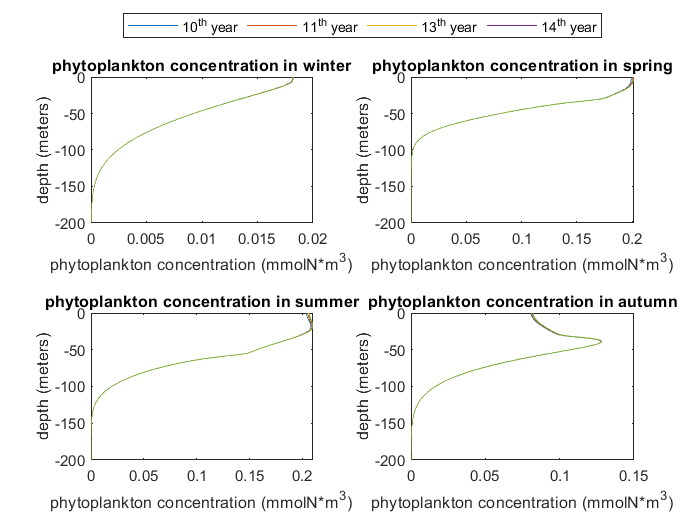

%Graph of winter
tiledlayout(2,2)
ax(1)=nexttile;
Ptest=dy([365*10 365*11 365*12 365*13 365*14],1:steps);
plot(Ptest',-z)
xlabel('phytoplankton concentration (mmolN*m^{3})')
ylabel('depth (meters)')
shading interp;
title('phytoplankton concentration in winter')
ax(2)=nexttile;
%Graph of spring
Ptest2=dy([365*10+91 365*11+91 365*12+91 365*13+91 365*14+91],1:steps);
plot(Ptest2',-z)
xlabel('phytoplankton concentration (mmolN*m^{3})')
ylabel('depth (meters)')
shading interp;
title('phytoplankton concentration in spring')
ax(3)=nexttile;
%Graph of summer
Ptest2=dy([365*10+183 365*11+183 365*12+183 365*13+183 365*14+183],1:steps);
plot(Ptest2',-z)
xlabel('phytoplankton concentration (mmolN*m^{3})')
ylabel('depth (meters)')
shading interp;
title('phytoplankton concentration in summer')
ax(4)=nexttile;
%graph of autumn
Ptest2=dy([365*10+274 365*11+274 365*12+274 365*13+274 365*14+274],1:steps);
plot(Ptest2',-z)
xlabel('phytoplankton concentration (mmolN*m^{3})')
ylabel('depth (meters)')
shading interp;
title('phytoplankton concentration in autumn')
hold off
lh =legend(ax(1),{'10^{th} year','11^{th} year','13^{th} year','14^{th} year'},'Location','NorthOutside','Orientation','Horizontal');
lh.Layout.Tile = 'North';

%Limiting factors

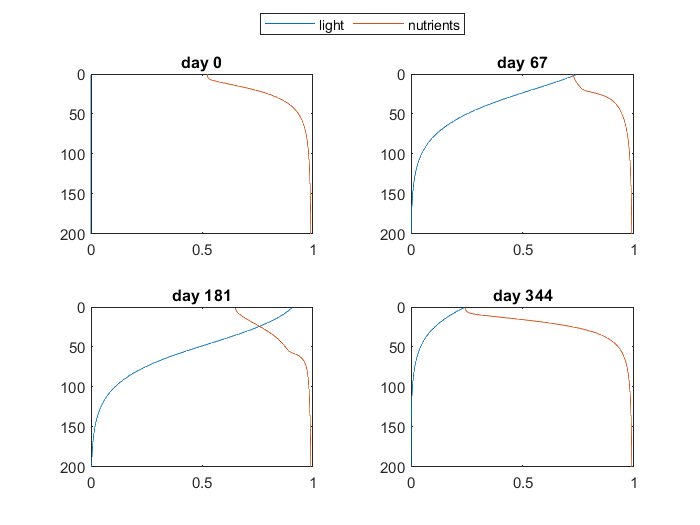

t=tiledlayout(2,2);
for i=[10*365 10*365+67 10*365+181 10*365+344]
    Nx=dy(i,steps+1:steps*2)';
    P2=dy(i,1:steps)';
    fN2=(Nx./(Nx+Hn));
    I=calclight(Iin,P2,steps,delta,k,Kbg,time(i));
    fI2=(I./(I+H));
   ax(i)= nexttile;
    plot(fI2,1:steps);
    hold on
    plot(fN2,1:steps);
    title(['day ' num2str(-365*10+i)])
    set(gca,'Ydir','reverse')
       hold off
       lh =legend(ax(10*365),{'light','nutrients'},'Location','NorthOutside','Orientation','Horizontal');
lh.Layout.Tile = 'North';    
end